### **WILL TIRONE **

### **MAT 275**

### **LAB 5**

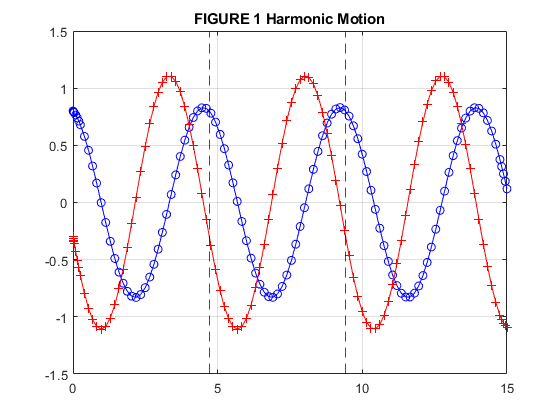

LAB05ex1
title 'FIGURE 1 Harmonic Motion'
xline((3*pi)/2, 'k--')
xline((6*pi)/2, 'k--')

**QUESTION 1**

a) Which curve represents y = y(t)? 

- By looking through the code, y = y(t) has an initial condition y(0) = 0.8 so it must be the blue curve. However, we can also see that, because of the change of variable, the red line 'v' represents its first derivative. Because this derivative is 0 where the red line reaches its max, the red line must also be y(t). 

b) What is the period of motion?

- Graphically, by using the cursor option on the figure, I can see that the first peak occurs at 3.392 and the second at 7.999, so the period is approximately 4.608. 

- Analytically, and more precisely, the period is given by $\frac{2\pi}{w_0} $ which in this case is $\frac{3\pi}{2}$. I have added dotted lines on the above plot to indicate the increments of the periods.

c) Will the mass come to rest? 

- No - the above example is undamped, so there is nothing preventing it from oscillating forever. This is supported graphically as it does not appear to be approaching 0 from 0 < t < 15. 

d) What is the amplitude? 

- This is represented by the maximum y-value the curve achieves; therefore, it can be found using max(): 

max(y)

ans = 0.8306

e) What is the maximum velocity...

- By looking at a table of t, y, and v values from the below, I've determined the maximum velocity is about 1.1 m/s which occurs at time t=3.39, 7.99, and 12.69

- The mass is at 0 when maximum velocity is obtained. 

A = [t y v]; 
B = [A(30,:); A(60,:); A(91,:)]

B =     3.3918    0.0703    1.1041
    7.9992   -0.0454    1.1062
   12.6902   -0.0683    1.1040


f) 

The natural frequency is  $w_0$ = $\sqrt\frac{k}{m}$ 

By observation, a very large m would result in a very small frequency and thus very long, drawn out waves of oscillation. A very high k would result in the opposite, with a high natural frequency resulting in a high rate of oscillation. Let's see if this is correct by running the script again...

This appears to be correct by looking at the graphs as well; also note that with a large m the velocity never exceeds y(t), while in the case of a large k, it does. This makes sense if you think about pulling on a very stiff spring - it will shoot forward with a lot of force resulting in a lot of oscillation with high velocity even with an "average" amount of weight attached. 

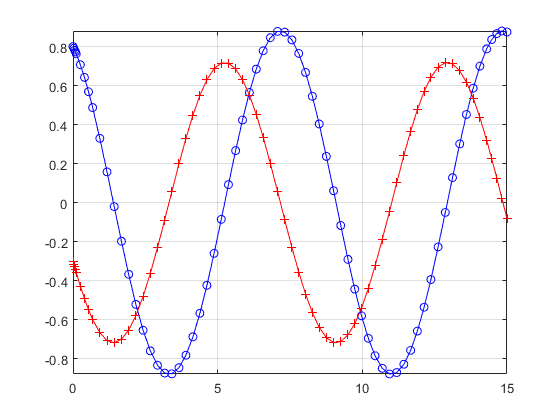

LAB05ex1 %with m=24;k=16

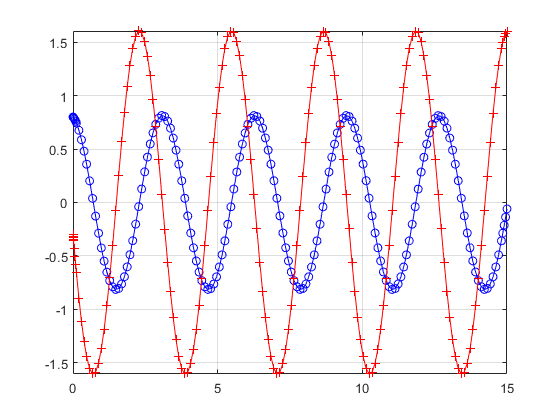

LAB05ex1 %with m=9,k=35

**QUESTION 2**

**a) Does the graph confirm the fact that the energy is conserved?**

- Since the plot of energy (the green line) is constant, energy is clearly conserved. 

- Additionally,  the derivative of energy is zero, further proving that it is constant / conserved

type LAB05ex1.m

clear all;     % clear all variables 
m = 9;  % mass [kg]
k = 35;  % spring constant [N/m]
omega0 = sqrt(k/m); 
y0 =0.8;  v0 = -0.3; % initial conditions
[t,Y] = ode45(@f,[0,15],[y0,v0],[],omega0); % solve for 0<t<15
y = Y(:,1); v = Y(:,2);  % retrieve y, v from Y 

E = (1/2) * m *v.^2 + (1/2)*k*y.^2;

figure(1); plot(t,y,'bo-',t,v,'r+-',t,E,'g');% time series for y and v 
grid on; axis tight; 
ylim([-2,14])
%---------------------------------------------------
function dYdt = f(t,Y,omega0); % function defining the DE 
y = Y(1); v = Y(2); 
dYdt=[ v ; - omega0^2*y ];
end


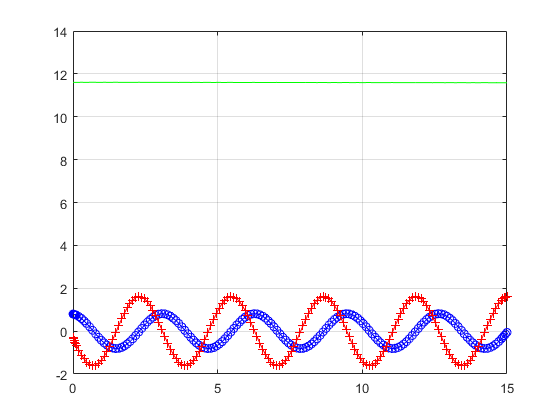

LAB05ex1

**b) Prove that **$\frac{dE}{dt} = 0$ 

1) $E = \frac{1}{2}mv^2 + \frac{1}{2}ky^2 $

2) $\frac{dE}{dt} = \frac{1}{2}m(2V\frac{dv}{dt}) + \frac{1}{2}k(2y\frac{dy}{dt})$

Utilizing Hooke's Law: 

3) $F = -ky$ 

and Newton's Second Law: 

4) $F = ma$

Rewriting: 

5) $m \frac{dv}{dt} = -ky$

substituting into 2) 


$$\frac{dE}{dt} = kyv - kyv = 0$$


QED

**c) Does the curve ever get close to the origin? Why or why not? What does that mean for the mass-spring system?**

- The curve never gets close to the origin; this indicates that the system will never reach a single point and is always in the steady-state portion of the solution, $y_{sp}$

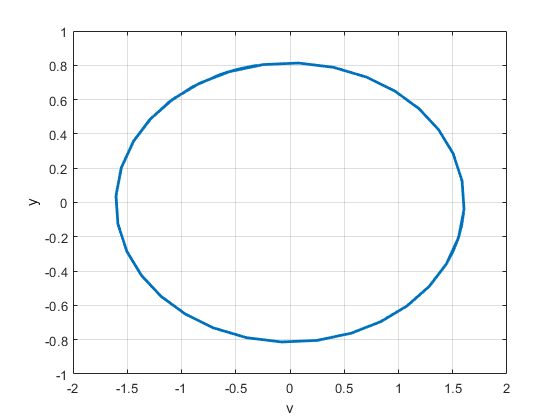

LAB05ex1 % supressed output of the first plot, it is identical to Question 2 a)

**Question 3**

type LAB05ex2.m

clear;     % clear all variables 
m = 9;  % mass [kg]
k = 16;  % spring constant [N/m]
c = 8;  % friction coefficient [Ns/m]
omega0 = sqrt(k/m); 
p = c/(2*m); 
y0 =0.8;  v0 = -0.3; % initial conditions

[t,Y] = ode45(@f,[0,15],[y0,v0],[],omega0, p); % solve for 0<t<15
y = Y(:,1); v = Y(:,2);% retrieve y, v from Y 
figure(1); plot(t,y,'bo-',t,v,'r+-');% time series for y and v 
legend('y(t)','v(t) = y(t)')
title 'Figure 2: Damped harmonic motion'
grid on; axis tight; 


%---------------------------------------------------
function dYdt = f(t,Y,omega0,p) % function defining the DE 
y = Y(1); v = Y(2); 
dYdt=[v; (-2*p*v) - (omega0^2)*y];   % fill-in dv/dt
end


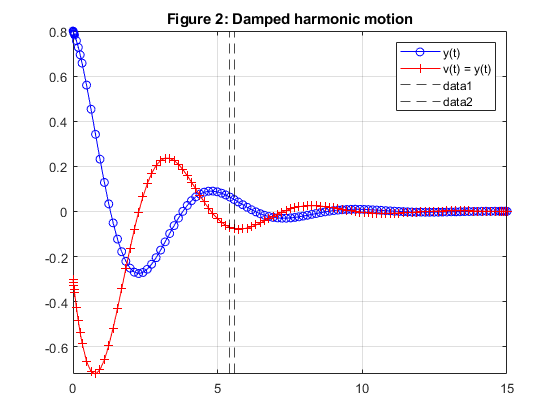

LAB05ex2
xline(5.424,'k--')
xline(5.5683, 'k--')

**a) For what minimal time... **

- The below loop simply looks through the absolute values of y, from beginning to end, and finds where they are less than 0.06. 

for i=1: length (y)
M(i)= max(abs(y(i:end )));
end
i = find (M <0.06); i = i(1)

i = 44

disp (['|y| <0.06 for t > t1 with ' num2str(t(i-1)) '< t1 <' num2str(t(i))])

|y| <0.06 for t > t1 with 5.424< t1 <5.5683


**b) What is the largest (in magnitude) velocity attained by the mass, and when is it attained? Answer by using the magnify button.**

for i=1: length (v)
    M(i)= max(abs(v(i:end )));
end
    i = find (M <0.06); 
    i = i(1)

i = 49

disp (['|v| <0.06 for t > t1 with ' num2str(t(i-1)) '< t1 <' num2str(t(i))])

|v| <0.06 for t > t1 with 6.1708< t1 <6.3235


**c) How does the size of c affect the motion?**

- since C is the damping coefficient, it will result in a longer time to reach equilibrium. For example, C=12 looks under damped,  C =24 looks critically damped, and C=54 looks over damped. 

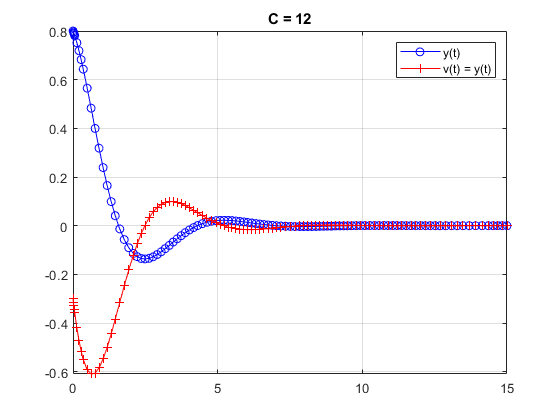

LAB05ex2

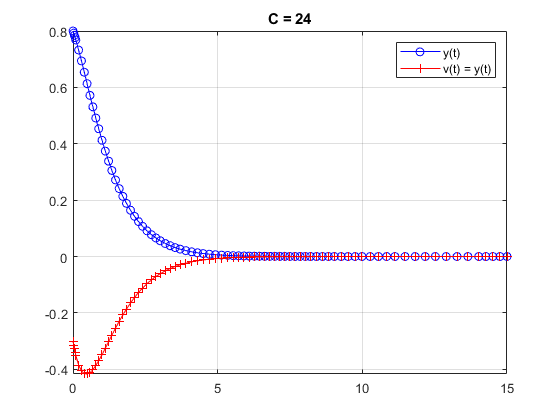

LAB05ex2

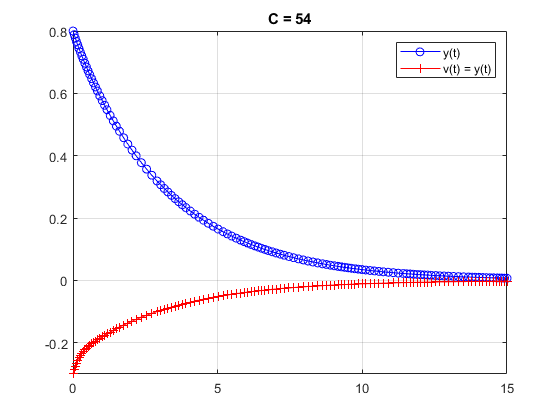

LAB05ex2

**d) Determine analytically the smallest (critical) value of c such that no oscillation appears in the solution.**

Given the DE: 


$$9y'' + cy' + 16y = 0 $$


We can find the critical value where the discriminant is equal to 0. Thus: 


$$c^2 -4(9)(16) = 0 \\
c^2 = 576 \\ 
c = \sqrt{576} \\ 
c = 24$$


As I assumed above, c = 24 was the critical value graphed in figure 2. 

**Question 4**

**a) **

The energy (green line) starts high initially and quickly shoots down to an equilibrium level. This makes sense, since the system is damped and energy would decrease with the presence of damping. 

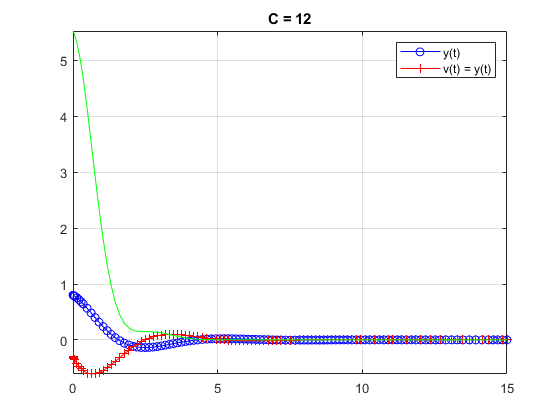

LAB05ex2

**b) **

Starting with: 

1) $my'' + cy' + ky = 0$

2) $-cy' = my'' + ky$

3) $\frac{dE}{dt} = y'(my'' + ky)$

substituting 2) into 3) 

4) $\frac{dE}{dt} = y'(-cy') = -c(y')^2$

Thus, using a negative value of c results in $\frac{dE}{dt} > 0 $ and a positive value of c results in $\frac{dE}{dt} < 0 $

**c) **

The spiral reaches the origin eventually - this is because the system does not oscillate forever and is damped. In contrast to Question 2 c), which never reached the origin and oscillated forever. 

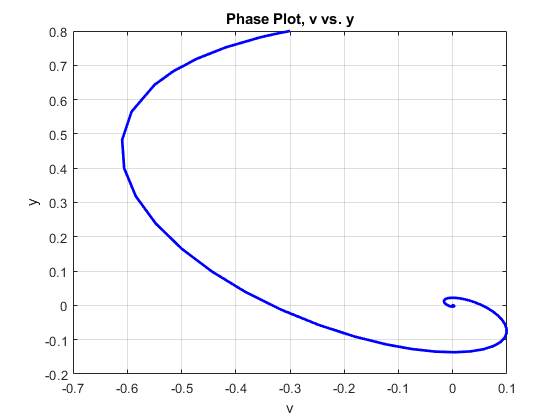

LAB05ex2